# Homework 1

**Name:** Jackson Lee

**Due Date: 1/30/23**

clear, clc

## Problem #1 - Charge on capacitor: measured vs. theoretical 

**a) Set up measured data (No output)**

t_m = [11,29,35,53,67,81];
Q_m = [1.3,2.4,2.4,3.7,3.9,3.7];

**b) Set up theoretical values (No output)**

t_t = 9:1:93;
Q_t = 5.1 .* (1-(exp((-t_t)./50)));

**c) Plot**

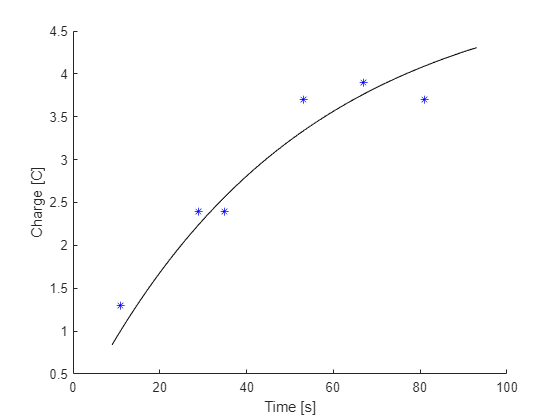

hold on
xlabel("Time [s]");
ylabel("Charge [C]");
plot(t_m,Q_m,"b*")
plot(t_t,Q_t,"k-")
hold off

## Problem #2 - Uniform beam with distributed load

% Set up variables
L=2000;
E=10000;
I=13000;
w0=170;
x=0:16:L;


**a) Displacement, **$y\left(x\right)$

    Formula: $y=\frac{w_0 }{120\textrm{EIL}}\left(2L^2 x^3 -{\textrm{xL}}^4 -x^5 \right)$

% Displacement code
y=((w0)./(120.*E.*I.*L).*((2*(L^2).*(x.^3))-(x.*(L^4))-(x.^5)));

**b) Slope, **$\theta \left(x\right)=\frac{\textrm{dy}}{\textrm{dx}}$

    Formula: $\theta =$ $\frac{w_0 }{120\textrm{EIL}\;}\left(6L^2 x^2 -L^4 -5x^4 \right)$

% Slope code
dy=((w0)./(120.*E.*I.*L).*((6*(L^2).*(x.^2))-(L^4)-(5.*(x.^4))));

**c) Moment, **$M\left(x\right)=\textrm{EI}\;\frac{d^2 y}{{\textrm{dx}}^2 }$

    Formula: $M=$$\left(\frac{w_0 }{120L}\left(12L^2 x-20x^3 \right)\right)$  

% Moment code
M=(w0/(120*L))*(((12*(L^2))*x)-(20*(x.^3)));

**d) Shear, **$V\left(x\right)=\textrm{EI}\;\frac{d^3 y}{{\textrm{dx}}^2 }$

    Formula: $V=$ $\left(\frac{w_0 }{120\textrm{IL}}\left(12L^2 -60x^2 \right)\right)$

% Shear code
V=(((w0)/(120*L))*((12*(L^2))-(60*(x.^2))));


**e) Plot a-d versus distance along the beam**

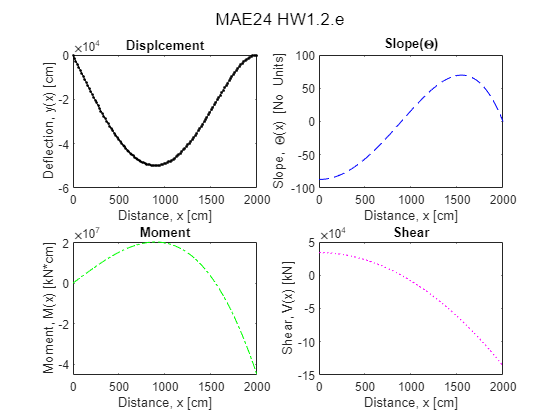

subplot(2,2,1);
plot(x,y,"k.-")
title("Displcement")
xlabel("Distance, x [cm]")
ylabel("Deflection, y(x) [cm]")

subplot(2,2,2);
plot(x,dy,"b--")
title("Slope(\Theta)")
xlabel("Distance, x [cm]")
ylabel("Slope, \Theta(x) [No Units]")

subplot(2,2,3);
plot(x,M,"g-.")
title("Moment")
xlabel("Distance, x [cm]")
ylabel("Moment, M(x) [kN*cm]")

subplot(2,2,4);
plot(x,V,"m:")
title("Shear")
xlabel("Distance, x [cm]")
ylabel("Shear, V(x) [kN]")

sgtitle("MAE24 HW1.2.e")

figure()

## Problem #3 - Ellipsoid tank

**a) Test #1 - Provide title and units, no return value**

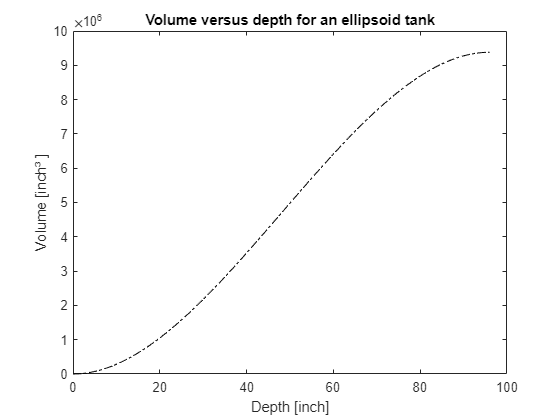

% Test #1 code
plot_title  = 'Volume versus depth for an ellipsoid tank'; 
ellipsoid_volume(48,216,plot_title,'inch')

**b) Test #2 - Use defaults, return volume**

% Test #2 code
V = ellipsoid_volume(10,2);

The volume of the tank is 167.5516 Cubic Meters

## Problem #4 - Manning's equation

**a) Display D matrix**

D = [.028, .0011, 21, 6.4;
     .033, .0001, 9, 3.3;
     .031, .0004, 20, 16.1;
     .021, .0006, 22, 12.6;
     .017, .0004, 14, 7.7;
     .022, .0008, 7, 14.9];
D(:,5) = (D(:,3) .* D(:,4)) ./ (D(:,3) + 2 * D(:,4))

D =     0.0280    0.0011   21.0000    6.4000    3.9763
    0.0330    0.0001    9.0000    3.3000    1.9038
    0.0310    0.0004   20.0000   16.1000    6.1686
    0.0210    0.0006   22.0000   12.6000    5.8729
    0.0170    0.0004   14.0000    7.7000    3.6667
    0.0220    0.0008    7.0000   14.9000    2.8342


**b) Calculations for V using single line of code and display V vector**

V = ((1./D(:,1)).*sqrt(D(:,2)).*(D(:,5).^(2/3)))

V =     2.9730
    0.4655
    2.1700
    3.7969
    2.7974
    2.5748


**c) Calculations for V using single line of code in a loop**

for n = 1:length(D(:,1))
    v = (1/D(n,1))*sqrt(D(n,2))*(D(n,5)^(2/3));
    fprintf("Channel %1.0f velocity = %.5f m/s\n", n, v)
end

Channel 1 velocity = 2.97299 m/s
Channel 2 velocity = 0.46549 m/s
Channel 3 velocity = 2.16999 m/s
Channel 4 velocity = 3.79685 m/s
Channel 5 velocity = 2.79745 m/s
Channel 6 velocity = 2.57482 m/s


## Problem #5 - Approximation and error

% Code for problem #5 here
termEst = zeros(1,7);
x = pi/3;

for k = 1:7
    if k == 1
        fprintf("# of terms      Estimate     True Error          MAPRE\n" + ...
                "---------- ------------- -------------- --------------\n")
        %10 13 14 14
    end

    termEst(k) =  ((-1)^(k-1))*((x^(2*k-1))/factorial(2*k-1));
    currentEst = sum(termEst(1:k));
    MAPRE = abs((currentEst-sum(termEst(1:(k-1))))/currentEst)*100;
    if k == 1
        fprintf("%10d %13.10f %14.10f %14s\n", k, currentEst, (sin(x)-currentEst), "N/A")
    else
        fprintf("%10d %13.10f %14.10f %14.10f\n", k, currentEst, (sin(x)-currentEst), MAPRE)
    end
   
end

# of terms      Estimate     True Error          MAPRE
---------- ------------- -------------- --------------


         1  1.0471975512  -0.1811721474            N/A


         2  0.8558007816   0.0102246222  22.3646406681
         3  0.8662952838  -0.0002698800   1.2114232200
         4  0.8660212717   0.0000041321   0.0316403464
         5  0.8660254451  -0.0000000413   0.0004819077
         6  0.8660254035   0.0000000003   0.0000048043
         7  0.8660254038  -0.0000000000   0.0000000338


## Problem #6 - Taylor series

**a) Calculate **$f_a \left(x\right)$** display in fprintf statement**

f = @(x) 5*x.^4 - 3*x - 7;
df_dx = @(x) 20*x.^3 - 3;
df2_d2x = @(x) 60*x.^2;

a = 1;

n_1 = df2_d2x(a)/factorial(2);
n_2 = (df_dx(a) - 2*a*(df2_d2x(a)/factorial(2)));
n_3 = f(a)-a*df_dx(a) +a^2*(df2_d2x(a)/factorial(2));

f_a = @(x) n_1*x.^2 + n_2*x + n_3;

fprintf("f_a(x) = %.4fx² + %.4fx + %.4f", n_1, n_2, n_3)

f_a(x) = 30.0000x² + -43.0000x + 8.0000

**b) Display exact answer and estimate the value of the function at the new value of x**

x = 2.5;
f_app = f_a(x);
f_ex = f(x);
fprintf("The exact value of f(%.1f) is %7.4f", x, f_ex)

The exact value of f(2.5) is 180.8125

fprintf("The approximate value of f(%.1f) if %7.4f", x, f_app)

The approximate value of f(2.5) if 88.0000

Calculating Error

MTPRE = abs(((f_ex-f_app)/f_ex)*100)

MTPRE = 51.3308

n = 2;
maxErr = 0.5*10.^(2-n)

maxErr = 0.5000

**c) Is this a reasonable approximation? Why or why not?**

No, because the MTPRE is 51.33%, and we defined in class using the Scarborough tolerance that with 2 significant digits the acceptable error          tolerance would be 0.5%, which is over 2 orders of magnitude less than the error in this estimation. 

**d) (Extra Credit) **

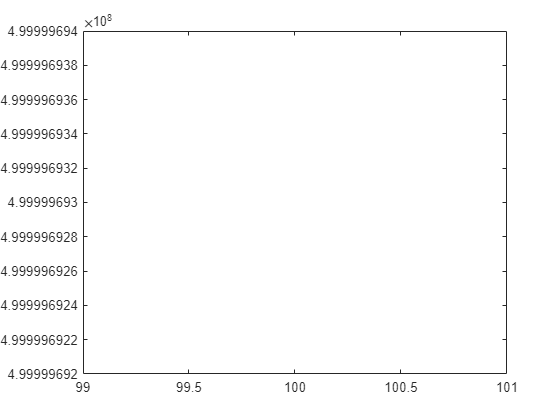

x_ = linspace(-100,100,1);
plot(x_,f(x_), "b--")%, 1, -5, "k.", f_a(x_), x_, "g-.", f_app, x, "cx", f_ex, x, "md")

## ellipsoid_volume function from problem 3

function  V = ellipsoid_volume(a,b,plot_title,units)
%  Calculate the volume of horizontal ellipsoidal tank
%
%  Syntax:
%     ellipsoid_volume(a,b,plot_title,units) - creates plot
%     V = ellipsoid_volume(a,b) - calculates total tank volume
%     V = ellipsoid_volume(a,b,plot_title,units) - does both
%
%  Inputs:
%     a          - vertical semi-axis
%     b          - horizontal radius
%     plot_title - string holding plot title
%     units      – optional inits string, default = ‘m’.
%
%  Output:
%     V - total volume of the tank

if nargin == 2
    V = (4/3)*pi*a*b^2;
    units = "Cubic Meters";
    fprintf("The volume of the tank is %.4f %s", V, units)
elseif nargin > 2
    h = linspace(0,2*a);
    volume = (pi/3).*(3*a-h).*((b^2.*h.^2)./a^2);
    plot(h,volume,"k-.")
    title(plot_title)
    
    if nargin == 4
        xstr = strcat("Depth [",units,"]");
        ystr = strcat("Volume [",units,"³ ]");
        
        ylabel(ystr)
        xlabel(xstr)
    else
        ylabel("Volume [m² ]")
        xlabel("Depth [m]")
    end
else
    error("Please input a Valid Command")
end
end